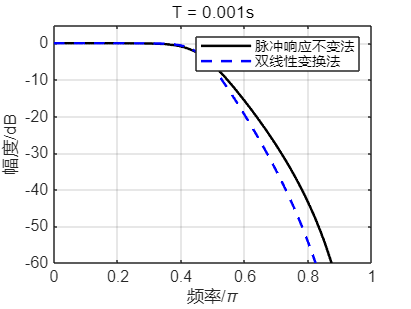

function [h_imp, h_bil, w] = design_filter(T, fp, fs, rp, rs)
    f = 1/T;                 % 采样频率
    
    % 归一化频率（以奈奎斯特频率为单位）
    Wp = fp/(f/2);           % 通带截止频率归一化
    Ws = fs/(f/2);           % 阻带截止频率归一化
    
    % 直接使用数字域设计（避免模拟到数字的转换）
    [N,Wn] = buttord(Wp, Ws, rp, rs);
    [n2,d2] = butter(N, Wn);
    
    % 对于脉冲响应不变法，使用较低阶数以提高稳定性
    N_imp = max(1, N-1);  % 确保阶数至少为1
    [B,A] = butter(N_imp, Wn);
    
    % 计算频率响应
    [h_imp,w] = freqz(B, A, 1024, 'whole');
    [h_bil,~] = freqz(n2, d2, 1024, 'whole');
    w = w/pi;
end

%% 主程序
% 参数设置
fp = 200;                     % 通带截止频率200Hz
fs = 350;                     % 阻带截止频率350Hz
rp = 3;                      % 通带波纹(dB)
rs = 35;                     % 阻带衰减(dB)

% 创建新图窗
figure(1);

% 第一部分：T = 0.001s
[h1_imp, h1_bil, w1] = design_filter(0.001, fp, fs, rp, rs);
plot(w1, 20*log10(abs(h1_imp)), 'k', ...
     w1, 20*log10(abs(h1_bil)), 'b--', 'LineWidth', 1.5);
grid on;
xlabel('频率/\pi');
ylabel('幅度/dB');
legend('脉冲响应不变法','双线性变换法');
title('T = 0.001s');
xlim([0, 1]);
ylim([-60, 5]);

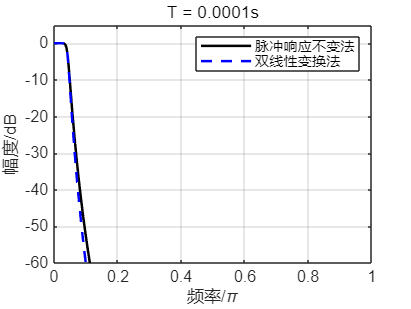


% 第二部分：T = 0.0001s
figure(2);
[h2_imp, h2_bil, w2] = design_filter(0.0001, fp, fs, rp, rs);
plot(w2, 20*log10(abs(h2_imp)), 'k', ...
     w2, 20*log10(abs(h2_bil)), 'b--', 'LineWidth', 1.5);
grid on;
xlabel('频率/\pi');
ylabel('幅度/dB');
legend('脉冲响应不变法','双线性变换法');
title('T = 0.0001s');
xlim([0, 1]);
ylim([-60, 5]);